# Fenado magnético

Este documento de matlab muestra la gráfica del comportamiento de un móvil desacelerado por un campo magnético.

En la siguiente parte de código, se piden los parámetros que se tomarán como base para la gráfica y se llama a dos funciones: ***campoM() ***y ***RK4().***

#### ***campoM()***

Obtiene el módulo del campo magnético para utilizarlo en ***RK4().***

#### ***RK4()***

Esta función recibe varios parámetros que representan las condiciones iniciales de la torre antes de ser frenada. Después, aplicando la Segunda Ley de Newton, se aplica al campo magnético creado por un dipolo y diferenciando respecto al tiempo. De esta forma, a través del método numérico de aproximación de ecuaciones diferenciales Runge-Kutta 4, obtenemos una gráfica que representa la posición del móvil en función al tiempo. La curva generada puede interpretarse como una desaceleración.

clear;
clc;
%I = -5;
%d = 10;
I = input("Intensidad (Amperes): ");
d = input("Dostancia entre los polos (m): ");
mR = campoM(d,I)

mR = 35.5585

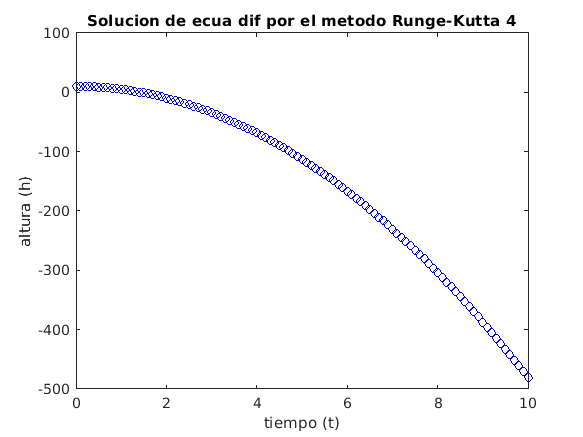

%h = 0.1;
%m = 0.5;
%h_i = 10;
%R = 23;
h = input("Intervalo de iteraciones (0<=h<=10): ");
m = input("Masa del dipolo (Kg): ");
hi = input("Altura de caída (m): ");
R = input("Resistecia del dipolo (Ohms): ");
RK4(mR, R, h_i, m, h);